# Delayed Feedback System for Franka Emika Panda

Add Path

clear;clc;
close all
addpath("PandaDyn\")
addpath("Dynamics\")
addpath("..\ReadYAML\")
config=ReadYaml("Configuration\FrankaEmikaPanda.yaml");

The system follows


$$M\left(\vec{q} (t)\right) \ddot{\vec{q}} (t) + C \left( \vec{q} (t), \dot{\vec{q}} (t) \right) \dot{\vec{q}} (t) + G \left( \vec{q} (t) \right) = - K_{p} \left( \vec{q} \left( t - \frac{3}{2} t_{s} \right) - \vec{q}_{d} \right) - K_{d} \dot{\vec{q}} \left( t - \frac{3}{2} t_{s} \right) - f \left( \dot{\vec{q}} \right),$$


where friction follows


$$f^{j} (\dot{q})= \frac{\varphi_{1,j}}{1 + e^{- \varphi_{2,j} \left( \dot{q}_{j} + \varphi_{3,j} \right)}} - \frac{\varphi_{1,j}}{1 + e^{- \varphi_{2,j} \varphi_{3,j}}}.$$


## Configurations

Sampling Time, Time Step & Simulation Time

dt=config.dt;
% ts=config.ts;
ts=7.87e-3;
SimulationTime=config.SimulationTime;
TimeSpan=0:dt:SimulationTime;

Initial Condition

TargetAngle=config.TargetAngle';
StateInitial=config.StateInitial';

Gains

Kp=diag(config.Kp);
Kd=diag(config.Kd);

Solver Option

option=ddeset('RelTol', config.DDE_RelTol, ...
    'AbsTol', config.DDE_AbsTol, ...
    "InitialStep",dt,"MaxStep",1.5*dt);

### Delayed Control Simulation

Controller

Controller=@(State)PDTorque(Kp,Kd,State,TargetAngle);

History Solution

history=@(t)get_HistorySolution(t,StateInitial);

Simulation

tic
sol=dde23(@(t,State,StateDelayed)DDE(t,State,StateDelayed,Controller),1.5*ts,history,TimeSpan,option);
toc

历时 235.677262 秒。


Show Time Steps

disp("Simulation time steps: "+num2str(length(sol.x)))

Simulation time steps: 67765


disp("Visualization time steps: "+num2str(length(TimeSpan)))

Visualization time steps: 1001


### Visualization for Delayed Control

Collect Data for Visualization

StateTimeHistoryDelay=deval(sol,TimeSpan,1:14);
eTimeHistoryDelay=StateTimeHistoryDelay(1:7,:)-TargetAngle;

$e-t$ Diagram

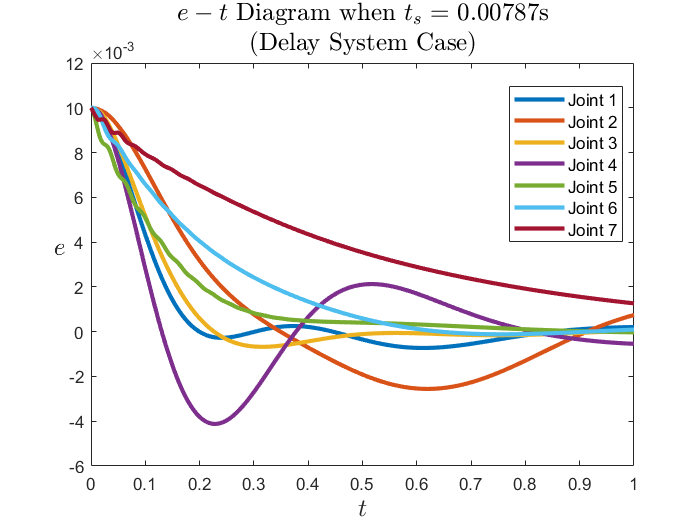

plot(TimeSpan,eTimeHistoryDelay,"LineWidth",2.5)
title(["$$ e-t $$ Diagram when $$t_s=$$ "+num2str(ts)+"s","(Delay System Case)"], ...
    "FontSize",15,"Interpreter","latex")
xlabel("$$t$$","FontSize",15,"Interpreter","latex")
ylabel("$$e$$","FontSize",15,"Rotation",pi/2,"Interpreter","latex")
legend("Joint 1","Joint 2","Joint 3","Joint 4","Joint 5","Joint 6","Joint 7","Fontsize",10,"Location","best")

$\dot{e}-t$ Diagram

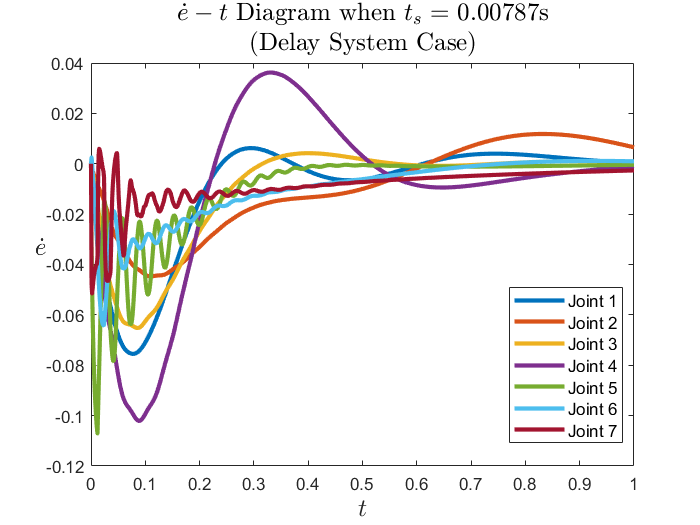

plot(TimeSpan,StateTimeHistoryDelay(8:14,:),"LineWidth",2.5)
title(["$$ \dot{e}-t $$ Diagram when $$t_s=$$ "+num2str(ts)+"s","(Delay System Case)"], ...
    "FontSize",15,"Interpreter","latex")
xlabel("$$t$$","FontSize",15,"Interpreter","latex")
ylabel("$$\dot{e}$$","FontSize",15,"Rotation",pi/2,"Interpreter","latex")
legend("Joint 1","Joint 2","Joint 3","Joint 4","Joint 5","Joint 6","Joint 7","Fontsize",10,"Location","best")

## Visualization in Cartesian Space

MDH parameter of Franka Emika Panda

mdl_panda

Trajectory of End Effector

EndEffectorLocDelay=panda.fkine(StateTimeHistoryDelay(1:7,:)').transl';

Target of End Effector

EndEffectorLocTarget=panda.fkine(TargetAngle).transl';

End Effector Trajectory

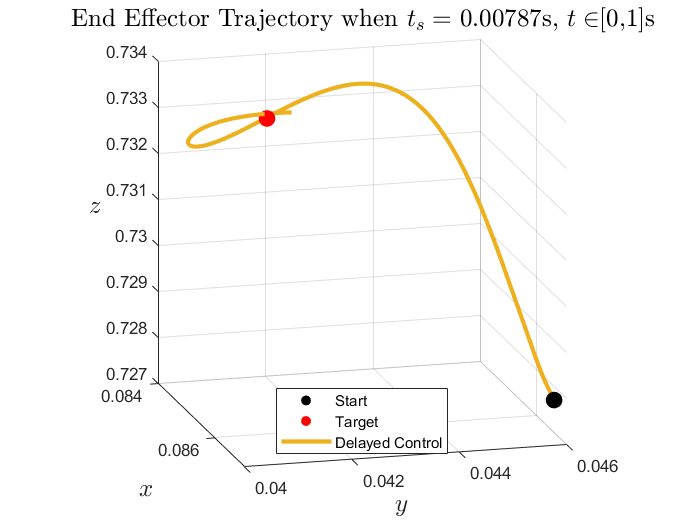

scatter3(EndEffectorLocDelay(1,1),EndEffectorLocDelay(2,1),EndEffectorLocDelay(3,1),100,"black","filled","o")
hold on
scatter3(EndEffectorLocTarget(1),EndEffectorLocTarget(2),EndEffectorLocTarget(3),100,"Red","filled","o")
plot3(EndEffectorLocDelay(1,:),EndEffectorLocDelay(2,:),EndEffectorLocDelay(3,:),"LineWidth",2.5)
hold off
title("End Effector Trajectory when $$t_s=$$ "+num2str(ts)+ ...
    "s, $$t \in$$[0,"+num2str(SimulationTime)+"]s", ...
    "FontSize",15,"Interpreter","latex")
view(75,15)
pbaspect([1 1 1])
legend("Start","Target","Delayed Control","Location","south")
xlabel("$$x$$","Interpreter","latex","FontSize",15)
ylabel("$$y$$","Interpreter","latex","FontSize",15)
zlabel("$$z$$","Interpreter","latex","FontSize",15,"Rotation",pi/2)
grid on

## Save Data

save("Data\StateTimeHistory_Delay_"+ ...
    datestr(datetime("today"),"yyyy_mm_dd")+".mat","StateTimeHistoryDelay")

Remove Path

rmpath("Dynamics\")
rmpath("PandaDyn\")
rmpath("..\ReadYAML\")